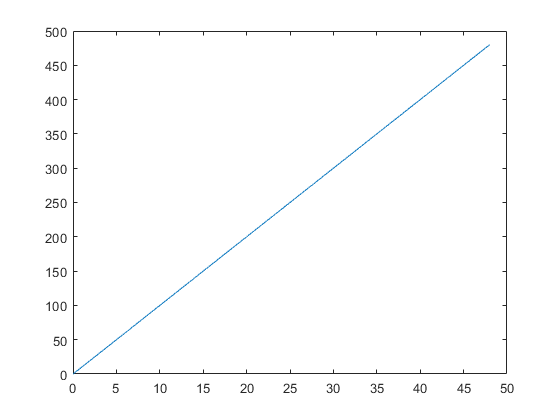

%%先生成速度随时间的变化序列
load path77
newx_y = path5;
x = newx_y(:,1);
y = newx_y(:,2);
T = newx_y(:,6);

diff_x = diff(x);
diff_x(end+1) = diff_x(end);
diff_y = diff(y);
diff_y(end+1) = diff_y(end);
%由x\y坐标得到横摆角坐标变化
yaw = atan2(diff_y,diff_x);
diff_yaw = diff(yaw);
diff_yaw(end+1) = diff_yaw(end);
yaw_rate = diff_yaw/0.01;
plot(T,x);

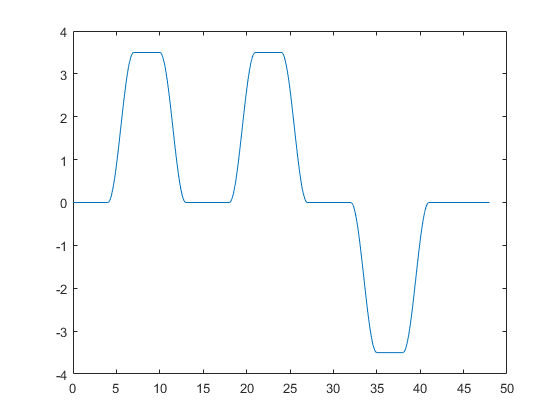

plot(T,y);

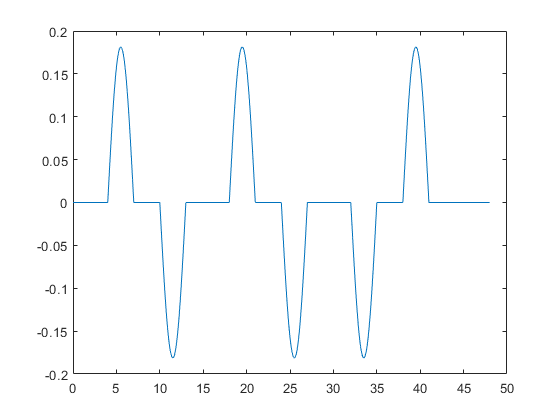

plot(T,yaw);

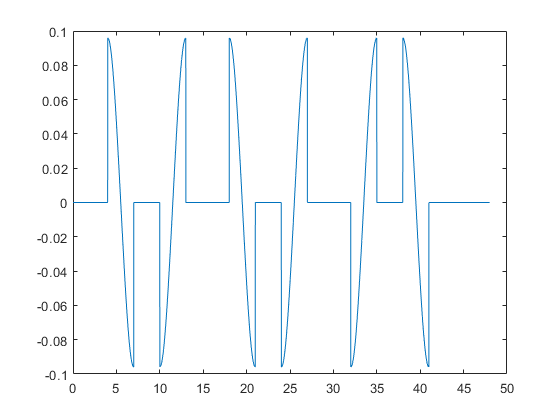

plot(T,yaw_rate);

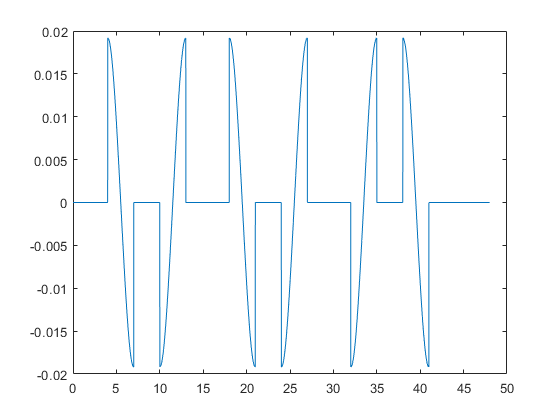

plot(T,newx_y(:,4));

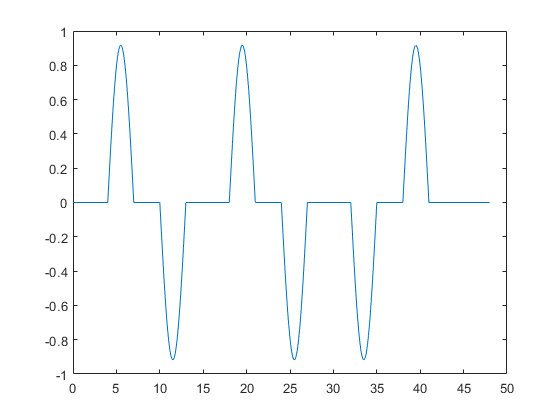

vy = diff_y/0.01;
plot(T,vy);

% yaw_rate_smooth = smoothdata(yaw_rate,'gaussian',6);
% plot(T,yaw_rate,T,yaw_rate_smooth);
% ref11 = [T',x',y',yaw',yaw_rate_smooth',vx'/3.6,vy'];

